% Auto-generated by Data Acquisition Toolbox Analog Input Recorder on 25-Jul-2018 13:16:53

## Create Data Acquisition Session

Create a session for the specified vendor. 

This is for configuring and operating data acquisition devices from the vendor.

'ni' is the vendor name for the device that you are creating a session for.

s = daq.createSession('ni'); 

## Set Session Properties

Set properties that are not using default values.

Sampling rate should be set to 10000 using s.Rate

Run time should be set to using s.DurationInSeconds

s.Rate = 10000;
s.DurationInSeconds = 5;

## Add Channels to Session

Add channels and set channel properties, if any.

Add an analog input channel with device ID Dev1 and channel ID ai0. 

Set the measurement type to Voltage.

addAnalogInputChannel(s,'Dev1','ai0','Voltage');

## Acquire Data

Start the session in foreground.

[data, timestamps, starttime] = startForeground(s);

## Log Data

Convert the acquired data and timestamps to a timetable in a workspace variable.

ai0 = data(:,1);
DAQ_1 = timetable(seconds(timestamps),ai0);

## Plot Data

Plot the acquired data on labeled axes.

The plot(x,y) command should be used to display the graph

The xlabel(), ylabel(), and legend() commands should be used to set respective titles

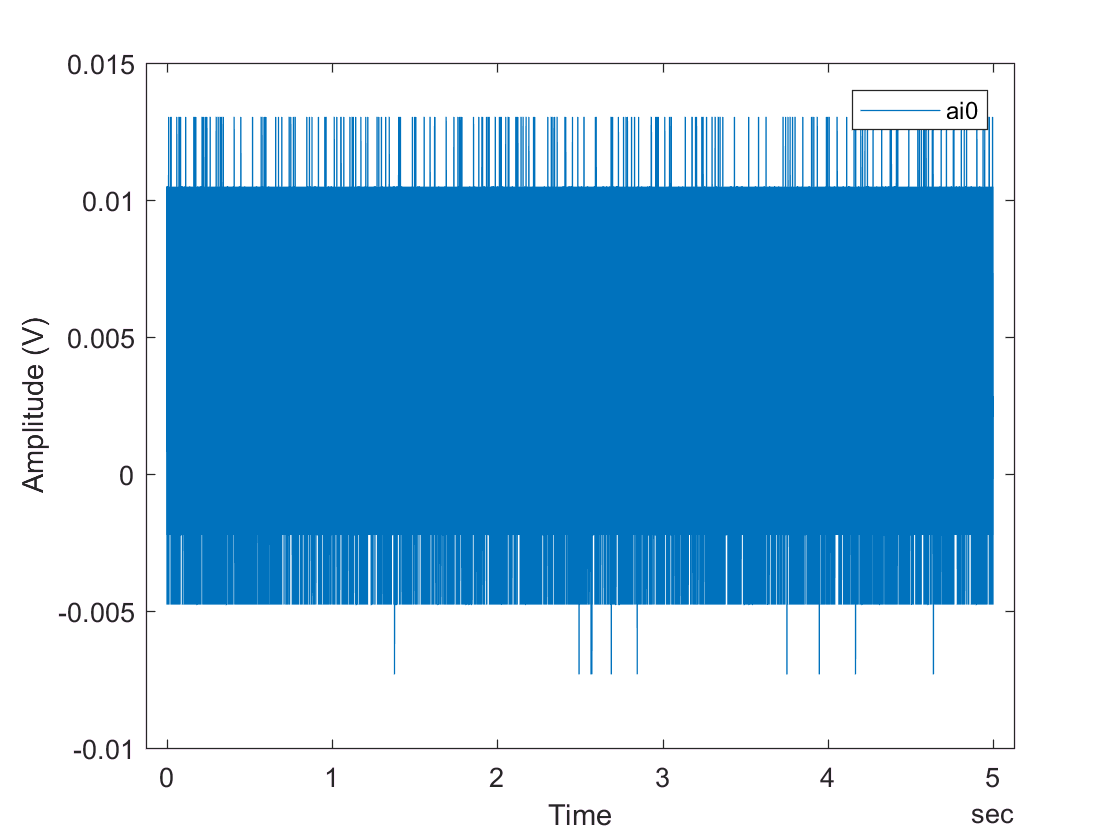

plot(DAQ_1.Time, DAQ_1.Variables)
xlabel('Time')
ylabel('Amplitude (V)')
legend(DAQ_1.Properties.VariableNames)

## Clean Up

Clear the session and channels, if any.

clear s